# Temperature Profile of a Vertical Ice Column

## Introduction

In order to describe the temperature profile of an ice sheet, glacier, or ice shelf, the heat exchange within a 1-D vertical column of ice can be modeled using advection-diffusion. The premise is that, as the ice shifts vertically (advection), the temperature gradient will change (diffusion).

Various numerical models have been used, with different physical phenomena considered. To describe the ice column, some of these phenomena can be included or omitted. A study by Moreno-Parada et al. (2024) included numerical solutions that involved multiple combinations of diffusion, vertical and horizontal advection, and strain heating. Another study assumed that horizontal advection and diffusion of heat are small enough to be negligible (Rezvanbehbahani et al., 2019). Methods employed in other studies include oxygen isotope profiles as a record of temperature variation (Robin, 1973), strain heating and creep instability (Clarke et al., 1977), and one including snow accumulation (Robin, 1955).

This model will use the advection-diffusion equation with multiple heat sources to solve the temperature profile of an ice sheet as it varies in time.

## Equations

As described, the main mechanism for heat transfer is advection and diffusion of ice vertically along the length of the column, and horizontally between other columns.

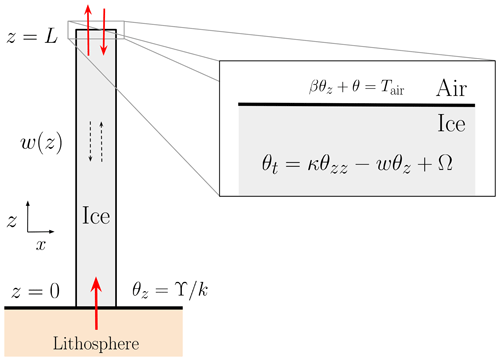

This illustration by Moreno-Parada et al. (2024) shows the setup for the problem, and various parameters that must be considered.

We can start by defining the height of the domain, L. According to Greve and Blatter (2009), ice thickness can vary from 1-3 km. Then, we can define the grid interval, Δz.

L = 3000;             %Ice thickness (m)
dz = 50;              %Grid space (m)
nz = L/dz;            %Number of grid spaces
z = linspace(0,L,nz)  %Grid (m)

z = 1.0e+03 *

         0    0.0508    0.1017    0.1525    0.2034    0.2542    0.3051    0.3559    0.4068    0.4576    0.5085    0.5593    0.6102    0.6610    0.7119    0.7627    0.8136    0.8644    0.9153    0.9661    1.0169    1.0678    1.1186    1.1695    1.2203    1.2712    1.3220    1.3729    1.4237    1.4746    1.5254    1.5763    1.6271    1.6780    1.7288    1.7797    1.8305    1.8814    1.9322    1.9831    2.0339    2.0847    2.1356    2.1864    2.2373    2.2881    2.3390    2.3898    2.4407    2.4915


The vertical advection of the ice, w(z), is assumed to vary linearly with depth (Clarke et al., 1977; Zotikov, 1986). The intial velocity, w0, ranges from -0.1 to -0.3 m/yr, implying a downward movement of ice (Golvinetto and Zwally, 2000; Spikes et al., 2004).

sec_yr = 86400*365  %Seconds per year

sec_yr = 31536000

w0 = -0.1/sec_yr;   %Velocity at top of ice column (m/yr)
w = w0.*(z./L)      %Vertical velocity profile (m/yr)

w = 1.0e-08 *

         0   -0.0054   -0.0107   -0.0161   -0.0215   -0.0269   -0.0322   -0.0376   -0.0430   -0.0484   -0.0537   -0.0591   -0.0645   -0.0699   -0.0752   -0.0806   -0.0860   -0.0914   -0.0967   -0.1021   -0.1075   -0.1129   -0.1182   -0.1236   -0.1290   -0.1344   -0.1397   -0.1451   -0.1505   -0.1559   -0.1612   -0.1666   -0.1720   -0.1774   -0.1827   -0.1881   -0.1935   -0.1989   -0.2042   -0.2096   -0.2150   -0.2204   -0.2257   -0.2311   -0.2365   -0.2419   -0.2472   -0.2526   -0.2580   -0.2634


An initial estimate of the ice temperature will be used as the first index for the advection-diffusion marching equation. We can assume the ice column has a linear temperature profile from -5°C at z = 0 to -30°C at z = L. The air temperature can be assumed constant throughout the simulation, and this will act as a Dirichlet boundary condition at the top of the ice column.

T_air = -30;                      %Surface air temperature (°C)
T = -5+(T_air-(-5))*(z/L)         %Temp of ice column at t=0 (°C)

T =    -5.0000   -5.4237   -5.8475   -6.2712   -6.6949   -7.1186   -7.5424   -7.9661   -8.3898   -8.8136   -9.2373   -9.6610  -10.0847  -10.5085  -10.9322  -11.3559  -11.7797  -12.2034  -12.6271  -13.0508  -13.4746  -13.8983  -14.3220  -14.7458  -15.1695  -15.5932  -16.0169  -16.4407  -16.8644  -17.2881  -17.7119  -18.1356  -18.5593  -18.9831  -19.4068  -19.8305  -20.2542  -20.6780  -21.1017  -21.5254  -21.9492  -22.3729  -22.7966  -23.2203  -23.6441  -24.0678  -24.4915  -24.9153  -25.3390  -25.7627


At the bottom of the ice column, we will employ a Neumann boundary condition dictated by geothermal heat and frictional heat at the ice-lithosphere interface. Values for geothermal heat, frictional heat, and ice conductivity are from Hooke (2005), Karlsson et al. (2021), and Ritz (1987) respectively.

G = 0.03;           %Geothermal heat (W/m^2)
Q = 0.3;            %Frictional heat (W/m^2)
k = 2;              %Ice conductivity (W/m/K)
kappa = 1.4e-6;     %Thermal Diffusivity of ice (m^2/s)
rho = 917;          %Ice density (kg/m^3)
cp = 2009;          %Specific heat capacity (J/kg*K)
theta_z0 = (G+Q)/k  %Temperature flux at z = 0 (K/m)

theta_z0 = 0.1650

## Numerical Methods

The resulting numerical methods that will be used are beneficial to understanding how the 1-D time dependent advection-diffusive heat equation perform as a verifier for the numerical ice-sheet solvers. Firstly, a discretization of our chosen vertical coordinate system will help in capturing boundary layer dynamics at the surface and bottom of the ice sheet layer. This will utilize a three-point asymmetric scheme for the boundary condition. Additionally, for our advection term, a scheme that will work symmetrically to look at how heat is transported as in relation to its surroundings. This central symmetric difference enables the the advection diffusion parameterization to perform better than other numerical models (such as asymmetrical). For reference, looking at a point i and its neighboring grid points at i+-1 to determine the change at the grid point i.

For a mathematical display :

That being implemented, Backward Euler can be used to account for the unconditionally stable solver within a theoretical multi-year ice melt event.

First, we can implement time step parameters. The total length of the simulation will be 40,000 years, as vertical advection of ice and diffusion of heat occur incredibly slowly.

%Time Stepping Parameters
t_end = 40000*sec_yr;             %Length of simulation (s)
dt = 100*sec_yr;                  %Time step (s)
n_steps = round(t_end/dt);        %Number of steps

Now, we take the initial linear temperature profile from before and set it as the first time step in a pre-allocated array.

%Initial Temperature Profile
T_history = zeros(nz,n_steps+1);  %Pre-allocate temperature array
T_history(:,1) = T;               %Set initial temperature

As stated before, the boundary condition at the bottom of the ice column is a Neumann boundary condition. We can create the matrix containing all constants in the advection-diffusion equation and modify it to include the boundary condition at z = 0.

%Bottom BC
M = zeros(nz,nz);
M(1,1) = -3/(2*dz);
M(1,2) =  4/(2*dz);
M(1,3) = -1/(2*dz);

The interior of the matrix (the grid spaces in between boundaries) can be set according to how we take information from advection and diffusion, respectively. For instance, we will create a diagonal matrix with three bands that correspond to the previous, current, and next grid spaces. Diffusion will inform all three, while advection will only influence the previous and next.

%Interior nodes (Symmetric advection & diffusion)
for i = 2:nz-1
    diff_term = kappa/(dz^2);
    adv_term = w(i)/(2*dz);
    M(i, i-1) = -dt*(diff_term-adv_term);
    M(i, i)   =  1+dt*(2*diff_term);
    M(i, i+1) = -dt*(diff_term+adv_term);
end

To complete the matrix, we can now implement the boundary condition at z = L. Since we assume the air temperature is constant, the corner of the matrix corresponding to the top of the ice column is unchanging. Here, a slight deviation from Moreno-Parada et al. (2024) is made. We assume the top of the ice column is perfectly insulated from the surface, so only the point z = L is equal to surface temperature.

%Top BC
M(nz,:) = 0;
M(nz,nz) = 1;

With the matrix created, we can now perform matrix operations to simulate the evolution of the temperature profile of the ice column.

%Loop as column-vector
for i = 1:n_steps
    vec = T(:);
    vec(1) = -(G+Q)/k;
    vec(nz) = T_air;
    T = M\vec;
    T_history(:,i+1)=T;
end

## Results

T_history

T_history =    -5.0000    6.9375   11.6172   15.3332   18.4949   21.2925   23.8293   26.1677   28.3492   30.4024   32.3483   34.2029   35.9785   37.6849   39.3301   40.9207   42.4621   43.9590   45.4153   46.8344   48.2194   49.5728   50.8969   52.1938   53.4653   54.7129   55.9382   57.1425   58.3269   59.4926   60.6406   61.7718   62.8870   63.9871   65.0726   66.1444   67.2029   68.2489   69.2827   70.3050   71.3161   72.3166   73.3068   74.2871   75.2579   76.2196   77.1723   78.1166   79.0526   79.9806
   -5.4237    0.3044    4.5690    8.0677   11.0960   13.8023   16.2719   18.5584   20.6982   22.7171   24.6342   26.4640   28.2182   29.9057   31.5341   33.1097   34.6376   36.1222   37.5673   38.9761   40.3517   41.6963   43.0123   44.3016   45.5660   46.8070   48.0261   49.2245   50.4034   51.5639   52.7070   53.8334   54.9442   56.0400   57.1215   58.1894   59.2442   60.2866   61.3171   62.3361   63.3441   64.3416   65.3289   66.3065   67.2746   68.2337   69.1840   70.1258   71.0

## Discussion

## Figures

Figure 1 shows the evolution of ice temperature throughout the column. Temperature is on the x-axis, and depth is the y-axis. Each curve represents a time step of 100 years.

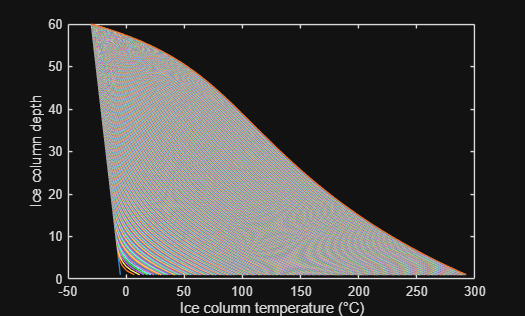

figure(1);
plot(T_history)
view([90 -90])
xlabel('Ice column depth')
ylabel('Ice column temperature (°C)')